K0 = 4.4;
T0 =5;
T1 =1.89;
T2 =5.31;
num = K0;
den = [T1*T2 T1+T2 1];
Gs = tf(num, den, 'InputDelay', T0)


Gs =
 
                       4.4
  exp(-5*s) * ---------------------
              10.04 s^2 + 7.2 s + 1
 
Continuous-time transfer function.



% zad 1 trnasmitancja dyskretna
Ts=0.5; %okres prbkowania
extrapolator='zoh';  % ekstrapolator zerowego rzędu
Gz = c2d(Gs, Ts, extrapolator)


Gz =
 
              0.0487 z + 0.04321
  z^(-10) * ----------------------
            z^2 - 1.678 z + 0.6986
 
Sample time: 0.5 seconds
Discrete-time transfer function.



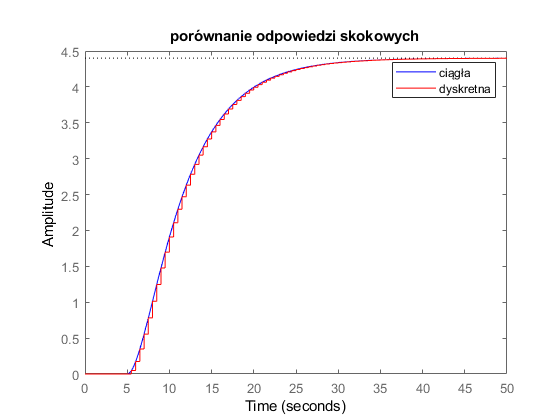

text='porównanie odpowiedzi skokowych';
step(Gs, 'b')
hold on
title(text)
step(Gz, 'r')
legend('ciągła', 'dyskretna')
%print(text, '-djpeg', '-r500')
hold off

% zad 2 rownanie rozniocowe
%y(k) = 1.678y(k-1) - 0.6986y(k-2) + 0.0487u(k-1) -+ 0.0432u(k-2)
a1=-1.678;
a2=0.6986;
a3=0;
b1=0.0487;
b2=0.0432;
b3=0;
a=[a1 a2 a3]

a =    -1.6780    0.6986         0


b=[b1 b2 b3]

b =     0.0487    0.0432         0


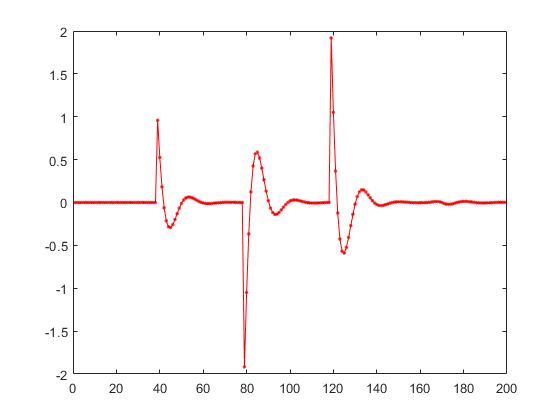

n_iter = 200;
% zad 3 regulator DMC
D=50;    %horyzont dynamiki
lambda=4;
N=6;    %horyzont predykcji
Nu=1;   %horyzont sterowania


A = diag(ones(Nu,1)).*lambda;   %Nu*Nu
Psi = diag(ones(N,1)); %N*N
s = get_s(a, b, D);

% generacja wektora wartości zadanych
Yzad_vec = vektor_zadanych(n_iter);
%Yzad_vec = skok_jednostkowy(n_iter).*2;

[U_global, Y_modelu_global] = DMC_sim(N, Nu, D, Yzad_vec, A, Psi, s, a, b);
plot(diff(U_global), '.-r')

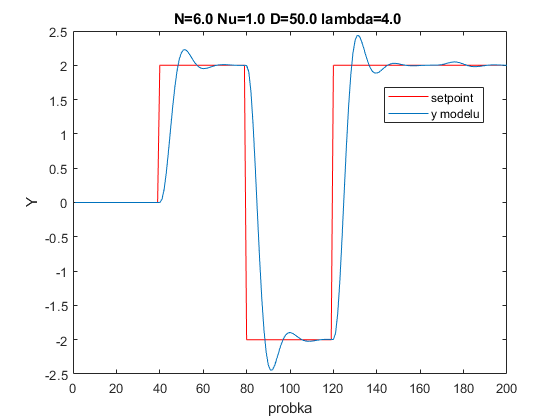

plot(Yzad_vec, 'r');
hold on
plot(Y_modelu_global)
legend('setpoint', 'y modelu', 'Location', 'best')
text=sprintf("N=%.1f Nu=%.1f D=%.1f lambda=%.1f ",N, Nu, D, lambda);
title(text)
xlabel('probka');
ylabel('Y');
%1probka->0.5s
print(text+'.jpg', '-djpeg', '-r500')
hold off

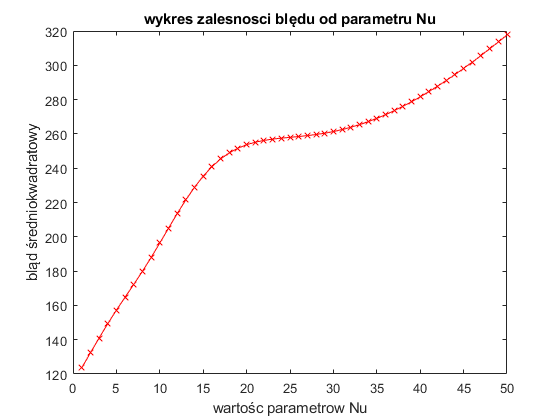

%badanie zależności jednej zmiennej. Yzad_vec ustawiana jest wyżej
n_tests = 50;
errors = zeros(n_tests, 1);
odpowiedzi = zeros(n_tests, n_iter);
sygnaly_sterujace = zeros(n_tests, n_iter);

N=6;
Nu=1;
%hold on
for zmienna=1:n_tests
    lambda=zmienna;
    A = diag(ones(Nu,1)).*lambda;   %Nu*Nu
    Psi = diag(ones(N,1)); %N*N
    s = get_s(a, b, D);
    [U_global, Y_modelu_global] = DMC_sim(N, Nu, D, Yzad_vec, A, Psi, s, a, b);
    errors(zmienna) = sum((Y_modelu_global-Yzad_vec).^2);
    odpowiedzi(zmienna,1:end) = Y_modelu_global;
    sygnaly_sterujace(zmienna, 1:end) = U_global;
end
plot(errors(1:end), 'x-r');
title('wykres zaleznosci blędu od parametru lambda');
xlabel('wartośc parametrow lambda');
ylabel('bląd średniokwadratowy');

print('wykres zaleznosci blędu od parametru lambda.jpg', '-djpeg', '-r500')


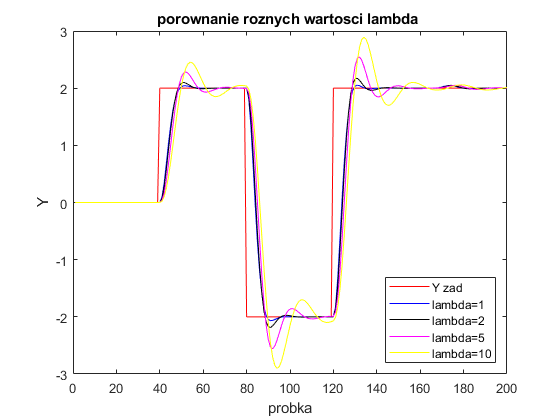

plot(Yzad_vec, 'r');
hold on
plot(odpowiedzi(1,1:end), 'blue')
plot(odpowiedzi(2,1:end), 'black')
plot(odpowiedzi(5,1:end), 'magenta')
plot(odpowiedzi(10,1:end), 'yellow')

text=sprintf("porownanie roznych wartosci lambda ");
title(text)
xlabel('probka');
ylabel('Y');
%1probka->0.5s
legend('Y zad','lambda=1', 'lambda=2', 'lambda=5', 'lambda=10', 'Location', 'southeast');
print(text+'.jpg', '-djpeg', '-r500')
hold off

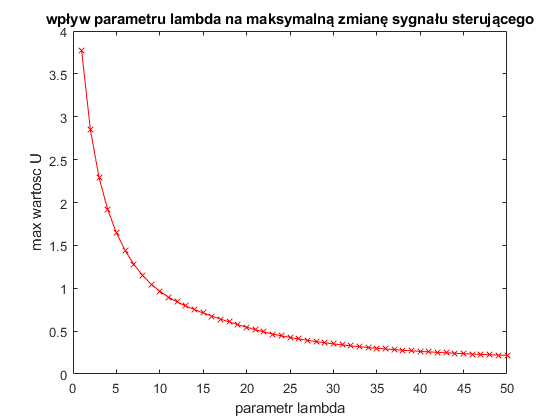

max_sygnal_diff = zeros(n_tests,1);
for i=1:n_tests
    max_sygnal_diff(i) = max(abs(diff(sygnaly_sterujace(i, 1:end))));
end
plot(max_sygnal_diff, 'x-r')
text = 'wpływ parametru lambda na maksymalną zmianę sygnału sterującego';
title(text);
xlabel('parametr lambda');
ylabel('max wartosc U')
print(text, '-djpeg', '-r500')

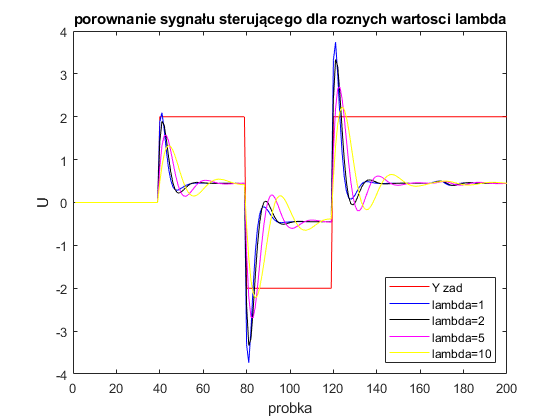


plot(Yzad_vec, 'r');
hold on
plot(sygnaly_sterujace(1,1:end), 'blue')
plot(sygnaly_sterujace(2,1:end), 'black')
plot(sygnaly_sterujace(5,1:end), 'magenta')
plot(sygnaly_sterujace(10,1:end), 'yellow')

text=sprintf("porownanie sygnału sterującego dla roznych wartosci lambda");
title(text)
xlabel('probka');
ylabel('U');
%1probka->0.5s
legend('Y zad','lambda=1', 'lambda=2', 'lambda=5', 'lambda=10', 'Location', 'southeast');
print(text+'.jpg', '-djpeg', '-r500')
hold off

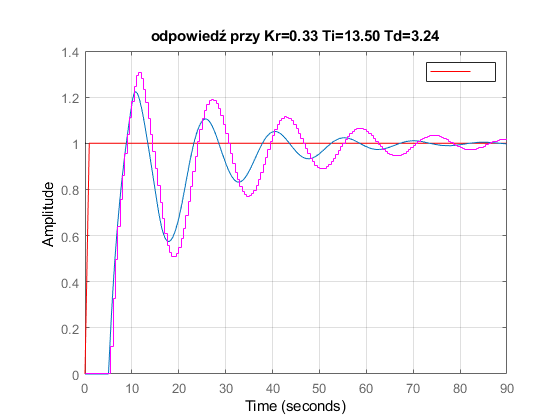


time_horizon = 90;
%PID tests
Kr=0.33;
Ti=13.5;
Td=3.24;
N=100;
C = pidstd(Kr,Ti, Td, N);
%C=C_auto;
fe = feedback(C*Gs, 1);

r0 = Kr * (1 + Ts/(2*Ti) + Td/Ts);
r1 = Kr * (Ts/(2*Ti) - 2*(Td/Ts) - 1);
r2 = Kr*Td/Ts;
[y_pid,u_pid,T] = PID_sim(Gz, time_horizon,r0,r1,r2);

x=linspace(0,time_horizon);
y=ones(size(x));
y(1)=0;
plot(x,y, 'r')
hold on
step(fe,time_horizon);
stairs(T, y_pid, 'magenta');
text=sprintf("odpowiedź przy Kr=%.2f Ti=%.2f Td=%.2f", Kr, Ti, Td);
title(text)
legend('u', 'y')
%print(text+'.jpg', '-djpeg', '-r500')
grid on
hold off